## Fit bioluminescence and virus titers data with SCG model

Load experimental data

clear;clc;
biolu_data_ko = importdata('biolu_data_ko.txt');

Optimize using fminsearch

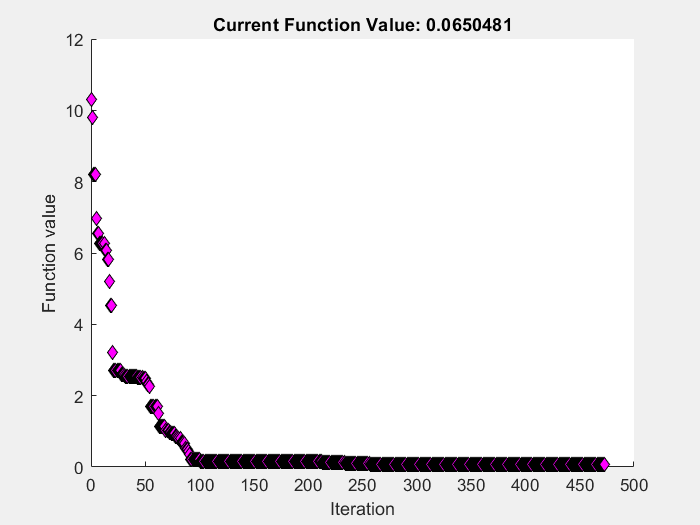

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.065048 



par_base = importdata('par_scg.txt');
par_base = par_base.data;

FitFcn = @(par_fit)Fit_err(biolu_data_ko, par_fit);

options_fmin = optimset('PlotFcns',@optimplotfval);
[p, fminres] = fminsearch(FitFcn, par_base, options_fmin);

format short g;
disp(p');

   2.4972e-05     0.094604        16872     0.087745

